addpath('include');
addpath('utils');
addpath('utils/plot');

clear, close, clc;

function T = DH_tFactory(DHp, n)
    T = eye(4);

    for i = n:-1:1
        d_i     = DHp(i, 1);
        theta_i = DHp(i, 2);
        r_i     = DHp(i, 3);
        alpha_i = DHp(i, 4);

        DH_T_i = ...
            tFactory(eye(3),        [0;   0; d_i])*...
            tFactory(Rz(theta_i),   [0;   0; 0])*  ...
            tFactory(eye(3),        [r_i; 0; 0])*  ...
            tFactory(Rx(alpha_i),   [0;   0; 0]);

        T = DH_T_i*T;
    end
end

function T = mDH_tFactory(DHp, n)
    T = eye(4);

    for i = n:-1:1
        d_i     = DHp(i, 1);
        theta_i = DHp(i, 2);
        r_i     = DHp(i, 3);
        alpha_i = DHp(i, 4);

        DH_T_i = ...
            tFactory(eye(3),        [r_i; 0; 0])*  ...
            tFactory(Rx(alpha_i),   [0;   0; 0])*  ... 
            tFactory(eye(3),        [0;   0; d_i])*...
            tFactory(Rz(theta_i),   [0;   0; 0]);

        T = DH_T_i*T;
    end
end

function plotDH(DHp, opt)
    plotFrame(eye(4), '<0>');
    hold on;
    axis equal;
    
    if (opt == "std")
        for i = 1:size(DHp, 1)
            T_i = DH_tFactory(DHp, i);
            plotFrame(T_i, ['<' num2str(i) '>']);
        end
    elseif (opt == "mod")
        for i = 1:size(DHp, 1)
            T_i = mDH_tFactory(DHp, i);
            plotFrame(T_i, ['<' num2str(i) '>']);
        end
    else
        print("plotDH: DH convention non defined")
    end
end

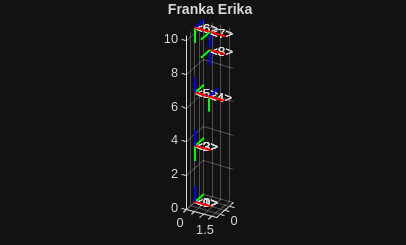

% Franka Erika - DH standard
DHp = @(q)...
      [ 0       q(1)    0       0;...
        3.33    q(2)    0       -pi/2;...
        0       q(3)    0       pi/2;...
        3.16    q(4)    0.825   -pi/2;...
        0       q(5)    -0.825  pi/2;...
        3.84    q(6)    0       -pi/2;...
        0       q(7)    0.88    -pi/2;...
        1.07    0       0       0;
      ];

% joint variable
q0 = deg2rad([0 0 0 0 0 0 0]);

% plot
figure
plotDH(DHp(q0), 'std'), title("Franka Erika");
view([30, 30])

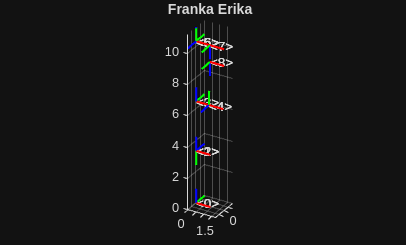

% Franka Erika - modified DH
DHp = @(q)...
      [ 3.33    q(1)    0       0;...
        0       q(2)    0       -pi/2;...
        3.16       q(3)    0       pi/2;...
        0       q(4)    0.825   pi/2;...
        3.84    q(5)    -0.825  -pi/2;...
        0       q(6)    0       pi/2;...
        0       q(7)    0.88    pi/2;...
        1.07    0       0       0;
      ];

% joint variable
q0 = deg2rad([0 0 0 0 0 0 0]);

% plot
figure
plotDH(DHp(q0), 'mod'), title("Franka Erika");
view([30, 30])

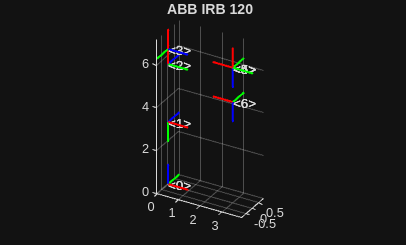

% ABB IRB 120 - DH standard toolDown pose DH parameters for tool-down pose
DHp = @(q)...
      [2.9      q(1)       0       -pi/2;...
       0        q(2)-pi/2  2.7    0;...
       0        q(3)       0.7   -pi/2;...
       3.02     q(4)       0       pi/2;...
       0        q(5)-pi/2  0       pi/2;...
       1.6      q(6)       0       0];

% joint variable
q0 = deg2rad([0 0 0 0 0 0]);

% plot
figure
plotDH(DHp(q0), 'std'), title("ABB IRB 120");
view([30, 30])

jacobian test

% Jacobian functor
function J = numericalJacobian(F, x0, h)
    x0 = x0(:);
    h  = h(:);

    f0 = F(x0);
    m  = numel(f0);
    n  = numel(x0);

    J = zeros(m,n);

    for i = 1:n
        dx = zeros(n,1);
        dx(i) = h(i);
        J(:,i) = (F(x0 + dx) - f0) / h(i);
    end
end

function v = pos_EE(DHp, q)
    T = DH_tFactory(DHp(q), length(q));   % full chain: 1..6
    v = T(1:3,4);
end

function v = attitude_EE(DHp, q)
    T = DH_tFactory(DHp(q), length(q));   % full chain: 1..6
    v = T(4:6,4);
end

% Correct function handle for EE position
F = @(q) pos_EE(DHp, q);

% Numerical Jacobian (safe, clear)
J = @(x,h,F) numericalJacobian(F, x, h);

% Point
x_0 = q0(:);
h   = 1e-5 * ones(size(x_0));

% Compute Jacobian (3 x n)
J_EE = J(x_0, h, F)

J_EE =    -0.0000    1.8000   -0.9000         0   -1.6000         0
    3.0200    0.0000    0.0000    1.6000   -0.0000         0
         0   -3.0200   -3.0200    0.0000    0.0000         0


inverse kinematic : istantaneous linear motion along x

v = J_EE\[1; 0; 0]

v =    -0.0000
    0.3704
   -0.3704
         0
         0
         0


% close all; 
% clear, clc; 
% 
% robot = loadrobot("frankaEmikaPanda");
% % showdetails(robot);
% 
% config = homeConfiguration(robot);
% 
% figure
% show(robot);
